% =========================================================================
% Lab 1.4 Load Cell — Plotting Script
% กราฟ 1: RAW ADC vs Weight (3 Sets, subplot แนวตั้ง)
% กราฟ 2: Real-time Weight vs Time
% =========================================================================
clear; clc; close all;

%% ── 1. โหลดข้อมูล Calibration ──────────────────────────────────────────
set1 = readtable('data/loadcell_set1/loadcell_set1.csv');
set2 = readtable('data/loadcell_set2/loadcell_set2.csv');
set3 = readtable('data/loadcell_set3/loadcell_set3.csv');

rt   = readtable('data/Lab1_4_Realtime_Continuous.csv');

%% ── 2. สมการเชิงเส้นเฉลี่ย (ใช้ร่วมกันทั้ง 3 Set) ──────────────────────
m_avg = 0.002557;
c_avg = 0.207051;
p_avg = [m_avg, c_avg];

% R² ของแต่ละ Set เทียบกับสมการเฉลี่ย
r2 = @(y, yhat) 1 - sum((y - yhat).^2) / sum((y - mean(y)).^2);
R2_1 = r2(set1.Target_Weight_kg, polyval(p_avg, set1.Avg_Raw_ADC));
R2_2 = r2(set2.Target_Weight_kg, polyval(p_avg, set2.Avg_Raw_ADC));
R2_3 = r2(set3.Target_Weight_kg, polyval(p_avg, set3.Avg_Raw_ADC));

fprintf('R² Set 1 = %.6f\n', R2_1);

R² Set 1 = 0.998691


fprintf('R² Set 2 = %.6f\n', R2_2);

R² Set 2 = 0.998309


fprintf('R² Set 3 = %.6f\n', R2_3);

R² Set 3 = 0.998480


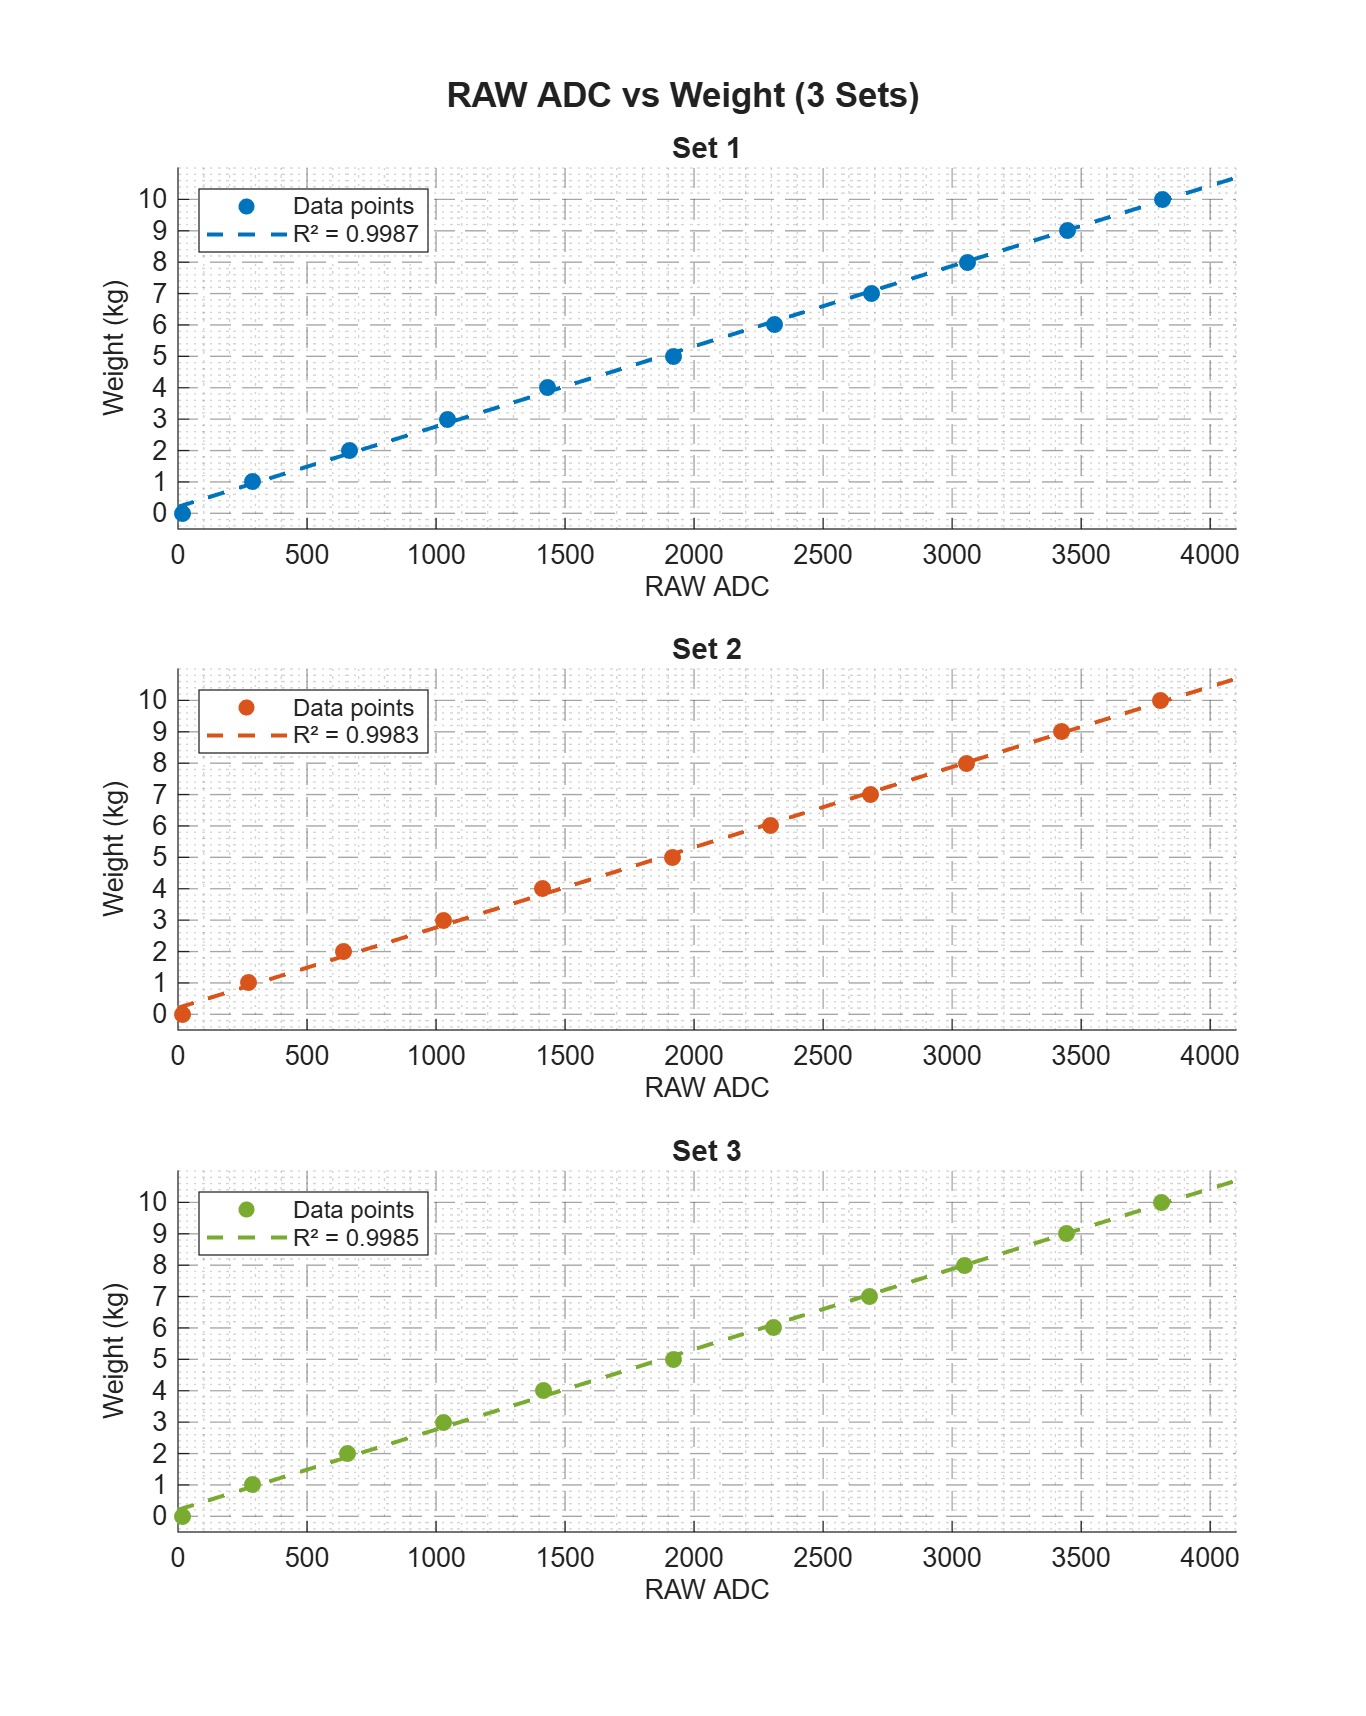


% x สำหรับ fit line
raw_fit = linspace(0, 4100, 200);

%% ── 3. กราฟ RAW ADC vs Weight (3 Subplots แนวตั้ง) ─────────────────────
colors = [
    0.00  0.45  0.74;   % น้ำเงิน  — Set 1
    0.85  0.33  0.10;   % ส้ม      — Set 2
    0.47  0.67  0.19;   % เขียว    — Set 3
];

datasets = {set1, set2, set3};
R2vals   = [R2_1, R2_2, R2_3];
labels   = {'Set 1', 'Set 2', 'Set 3'};

figure('Name', 'RAW ADC vs Weight: All Sets', ...
       'Position', [100 50 700 900]);

for k = 1:3
    ax = subplot(3, 1, k);

    d = datasets{k};
    c = colors(k, :);

    % Scatter จุดข้อมูล
    scatter(d.Avg_Raw_ADC, d.Target_Weight_kg, 40, c, 'filled', ...
        'DisplayName', 'Data points');
    hold on;

    % เส้นประ fit line (สมการเฉลี่ย) พร้อมแสดง R²
    plot(raw_fit, polyval(p_avg, raw_fit), '--', ...
        'Color', c, 'LineWidth', 1.5, ...
        'DisplayName', sprintf('R² = %.4f', R2vals(k)));

    % ตกแต่ง
    title(labels{k}, 'FontSize', 11, 'FontWeight', 'bold');
    xlabel('RAW ADC', 'FontSize', 10);
    ylabel('Weight (kg)', 'FontSize', 10);
    legend('Location', 'northwest', 'FontSize', 9);

    xlim([0 4100]);
    ylim([-0.5 11]);
    yticks(0:1:10);

    grid on;
    ax.XMinorGrid     = 'on';
    ax.YMinorGrid     = 'on';
    ax.GridAlpha      = 0.4;
    ax.MinorGridAlpha = 0.2;
    ax.GridLineStyle  = '--';

    hold off;
end

sgtitle('RAW ADC vs Weight (3 Sets)', ...
    'FontSize', 13, 'FontWeight', 'bold');

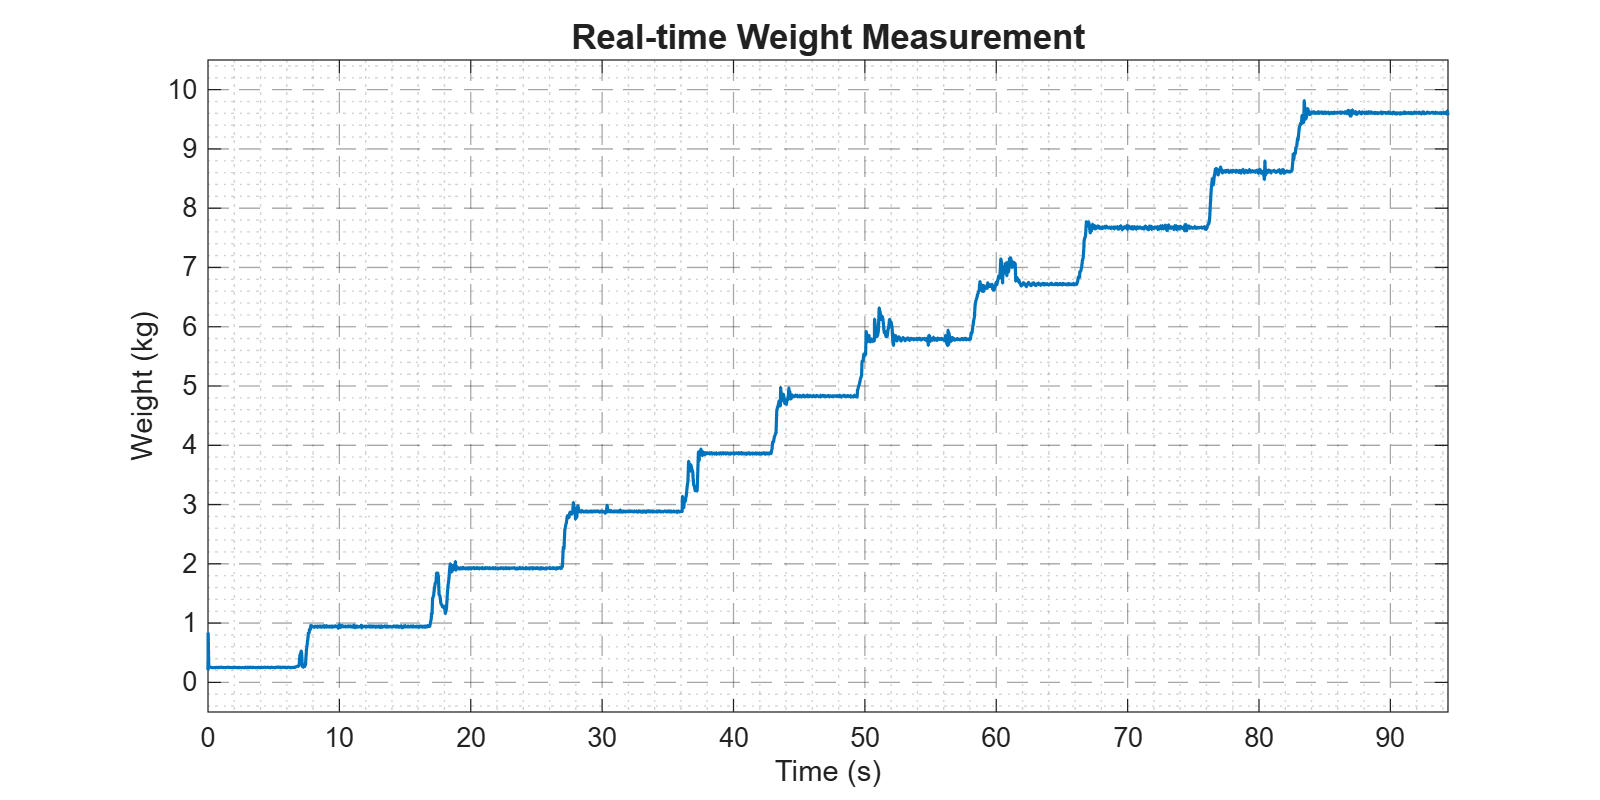


%% ── 4. กราฟ Real-time Weight vs Time ────────────────────────────────────
figure('Name', 'Real-time Weight vs Time', ...
       'Position', [820 50 800 400]);

plot(rt.Time_sec, rt.Measured_Weight_kg, ...
    'Color', [0.00 0.45 0.74], 'LineWidth', 1.2);

title('Real-time Weight Measurement', 'FontSize', 13, 'FontWeight', 'bold');
xlabel('Time (s)',  'FontSize', 11);
ylabel('Weight (kg)', 'FontSize', 11);

xlim([0 max(rt.Time_sec)]);
ylim([-0.5 ceil(max(rt.Measured_Weight_kg)) + 0.5]);
yticks(0:1:ceil(max(rt.Measured_Weight_kg)) + 1);

grid on;
ax2 = gca;
ax2.XMinorGrid    = 'on';
ax2.YMinorGrid    = 'on';
ax2.GridAlpha     = 0.4;
ax2.MinorGridAlpha = 0.2;
ax2.GridLineStyle  = '--';

% =========================================================================
% Lab 1.4 Load Cell — ตารางอภิปรายผล
% เปรียบเทียบ Load Cell vs Digital Scale ด้วย Absolute Error (kg)
% หมายเหตุ: Error_kg = Measured - Target (signed)
% =========================================================================

%% โหลดข้อมูล
set1 = readtable('data/loadcell_set1/loadcell_set1.csv');
set2 = readtable('data/loadcell_set2/loadcell_set2.csv');
set3 = readtable('data/loadcell_set3/loadcell_set3.csv');

%% คำนวณค่าเฉลี่ย Measured Weight จากทั้ง 3 Set
target   = set1.Target_Weight_kg;
measured = (set1.Measured_Weight_kg + ...
    set2.Measured_Weight_kg + ...
    set3.Measured_Weight_kg) / 3;

%% คำนวณ Absolute Error
abs_error = abs(measured - target);

%% สร้างตาราง
T = table(target, measured, abs_error, ...
    'VariableNames', {'Target_Weight_kg', 'Avg_Measured_kg', 'Abs_Error_kg'});

disp('ตารางเปรียบเทียบ Load Cell vs Digital Scale');

ตารางเปรียบเทียบ Load Cell vs Digital Scale


disp(T);

    Target_Weight_kg    Avg_Measured_kg    Abs_Error_kg
    ________________    _______________    ____________

            0               0.25395           0.25395  
            1               0.93104          0.068957  
            2                1.8811           0.11886  
            3                2.8509           0.14906  
            4                3.8383           0.16168  
            5                 5.114           0.11403  
            6                6.1021            0.1021  
            7                 7.068          0.068031  
            8                8.0167           0.01669  
            9                8.9935         0.0064743  
           10                9.9502          0.049765  




%% พิมพ์ Mean Absolute Error
mae = mean(abs_error);
fprintf('\nMean Absolute Error = %.4f kg\n', mae);


Mean Absolute Error = 0.1009 kg



%% Export เป็น CSV
writetable(T, 'Lab1_4_Discussion_Table.csv');
fprintf('บันทึกไฟล์ Lab1_4_Discussion_Table.csv เรียบร้อยแล้ว\n');

บันทึกไฟล์ Lab1_4_Discussion_Table.csv เรียบร้อยแล้ว
